# DC motor postion control: Root locus

## Requirements

- Settling time less than 0.040 seconds

- Overshoot less than 16%

- No steady-state error, even in the presence of a step disturbance input

## System

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;
s = tf('s');
sys = K/(s*((J*s+b)*(L*s+R)+K^2));

## Open-Loop Response

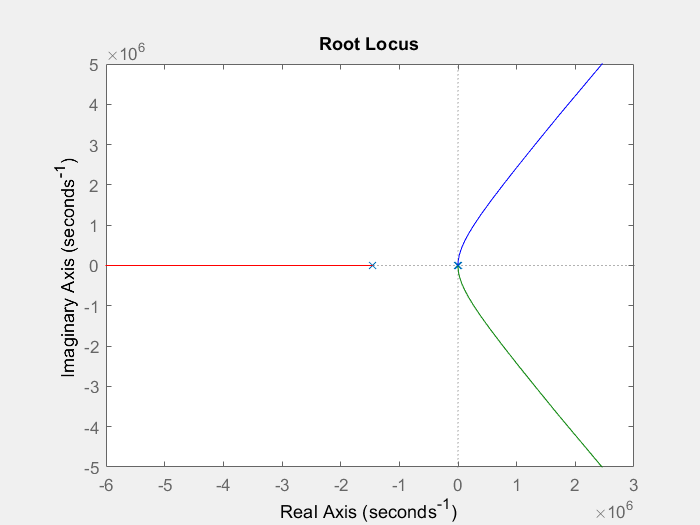

rlocus(sys);

This indicates that for a single P control the system would not be stable

## Model Reduction

Since one pole is really far to the left, we can approximate the system using a second-order system. The approximation should make sure the system has the same DC gain. And the new transfer function H(s) is an approximation of the old transfer function G(s) by. And this command can be done by MATLAB command ***minreal***


$$H\left(s\right)=G\left(s\right)*\left(\frac{s}{p_{\mathrm{max}} }+1\right)\approx G\left(s\right)$$


poles = pole(sys);
sys_reduced= minreal(sys*(s/max(abs(poles)) + 1))


sys_reduced =
 
      2122
  -------------
  s^2 + 59.23 s
 
Continuous-time transfer function.



## Reduced Model open loop

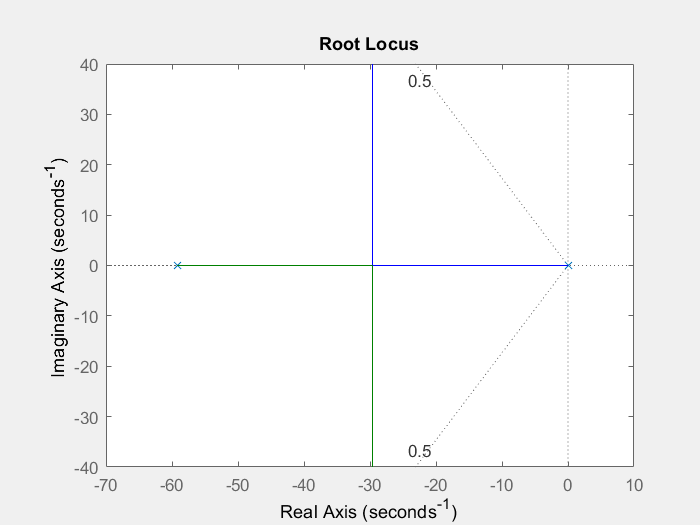

rlocus(sys_reduced);
sgrid(0.5, 0);

## PID design

For I and PI control, one can not have the roles in the region, so we need pid control, and we place two zeros far to the left of -59.6 poles to make the root locus go leftward. We place one zeros at -60 to cancel the poles, and one at -70

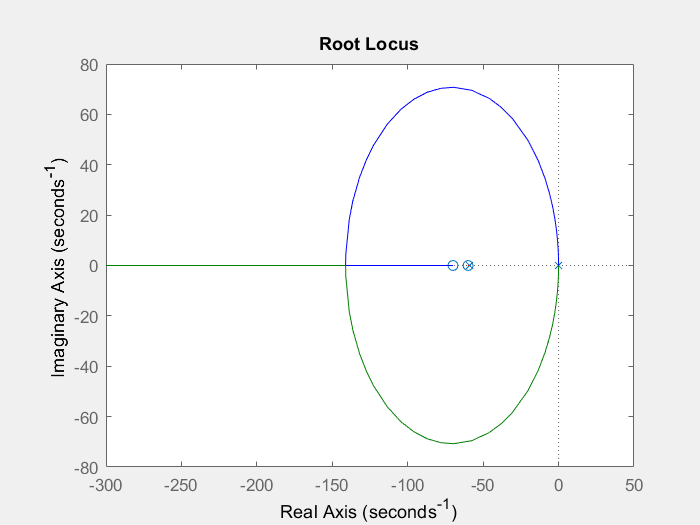

C = (s + 60)*(s + 70) / s;
rlocus(C*sys_reduced);

Since one pole and one zero cancels each other, we can simplify this model again. Let's reduce our new model again by performing the zero-pole cancelation using the **minreal** command. We pass 0.1 as a tolerance parameter as follows. The root locus for this further reduced system with controller is shown below. Note how closely it resembles the root locus without the pole-zero cancelation.

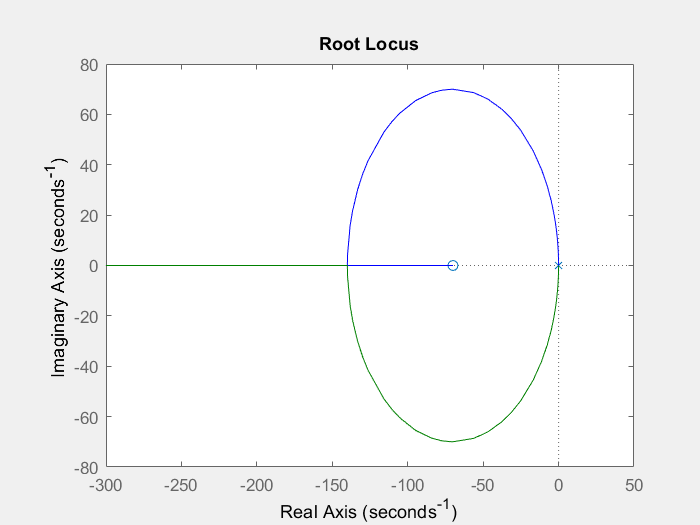

sys_new = minreal(C*sys_reduced, 0.1);
rlocus(sys_new);

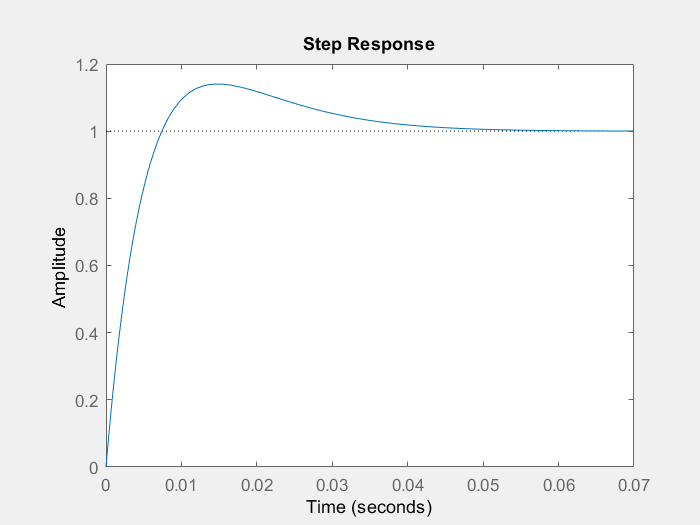

% [K1, poles] = rlocfind(sys_new);
K1 = 0.125;
sys_cl = feedback(K1*sys_new, 1);
step(sys_cl);

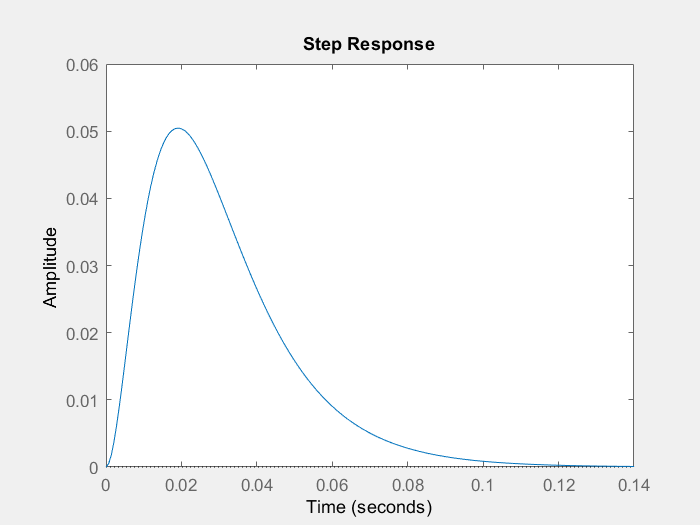

% look at the disterbunce response
sys_dis = feedback(sys, K1*C);
step(sys_dis)